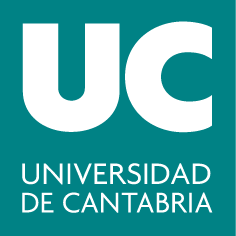

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **4. Cálculo diferencial**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Límite

El comando` limit `permite calcular directamente el límite de una función, ya sea esta anónima o simbólica.

**Ejemplo:** Calculamos los siguientes límites:

a) $$\lim\limits_{x\to\infty} \frac{x^4 - x^3 + 5}{3x^4 + x^2 - 4x}$$

clearvars
syms x real                                  % defino x como variable simbolica real
f = @(x)  (x^4 - x^3 + 5) / (3*x^4 + x^2 - 4*x);  % funcion anonima
L = limit(f, x, inf)

$$L = \frac{1}{3}$$

Para pasar a formato decimal podemos recurrir al comando `double`:

Lnum = double(L)

Lnum = 0.3333

b) $$\lim\limits_{x\to0} \frac{(1-\cos x)^2}{2sen^4x - sen^5x}$$

Podemos definir $f(x)$ como una función anónima

f = @(x)  (1-cos(x))^2 / (2*sin(x)^4 - sin(x)^5);
L = limit(f, x, 0)

$$L = \frac{1}{8}$$

#### Límites laterales

Los límites laterales:

- por la derecha: $$\lim\limits_{x \rightarrow a+} f(x) = \lim\limits_{h \rightarrow 0} f(a+h) $, $h>0$$

- por la izquierda: $$\lim\limits_{x \rightarrow a-} f(x) = \lim\limits_{h \rightarrow 0} f(a-h) $, $h>0$$

Recuerda que **el límite de una función en un punto existe si, y sólo si, existen los dos límites laterales en dicho punto y ambos coinciden:**


$$$$\lim\limits_{x \rightarrow a} f(x) = \ell  \Leftrightarrow\lim\limits_{x \rightarrow a+} f(x) =  \lim\limits_{x \rightarrow a-} f(x) = \ell$$$$


 **Ejemplo:** $$\lim\limits_{x\to0} \frac{sen\mid{x}\mid}{x}$$

clearvars
syms x real
f = sin(abs(x)) / x;

1. Calculamos límite por la derecha:

L_der = limit(f, x, 0, 'right')

$$L\_der = 1$$

2. Calculamos límite por la izquierda:

L_izq = limit(f, x, 0, 'left')

$$L\_izq = -1$$

Ambos existen, pero no coinciden. Por lo tanto, el límite $$\lim\limits_{x\to0} \frac{sen\mid{x}\mid}{x}$$ no existe:

L = limit(f, x, 0)

$$L = \mathrm{NaN}$$

#### Continuidad

A partir del cálculo de límites podemos estudiar la continuidad de una función. Para ello será conveniente conocer el comando `solve`, que permite resolver sistemas de ecuaciones. En el caso de una sola ecuación con una única incógnita, su sintaxis es la siguiente:

**Ejemplo: **Resolvemos la ecuación $x^2 - 5x-6 = 0$ 

syms x real
raices1 = solve(x^2 - 5*x - 6 == 0)   % raices ecuacion segundo grado --> x = {-1,6}

$$raices1 = \left(\begin{array}{c} -1\\ 6 \end{array}\right)$$

raices2 = solve(x^2 - 5*x - 6)        % equivalente a la orden anterior

$$raices2 = \left(\begin{array}{c} -1\\ 6 \end{array}\right)$$

El comando `solve` está diseñado para trabajar con expresiones simbólicas. Por tanto, en el caso de funciones anónimas, habría que convertirlas antes al tipo simbólico con ayuda del comando `sym`:

f = @(x)  4*x^2 - x;
% raices = solve(f)        % no permitido
raices = solve(sym(f))   % permitido --> x = {0, 1/4}

$$raices = \left(\begin{array}{c} 0\\ \frac{1}{4} \end{array}\right)$$

El resultado devuelto por` solve `también es una expresión simbólica:

R = double(raices)  % paso a decimal

R =          0
    0.2500


**Ejemplo**: Estudia la continuidad de la función $$f(x) = \frac{x}{x^2-x}$$

1. Definimos la función: 

clearvars
syms x real
f(x) =  x / (x^2 - x);

2. Hallamos los puntos de discontinuidad: $f(x)$ no esta definida en los puntos en los que el denominador se anule:

puntos_discontinuidad = double(solve(x^2 - x))

puntos_discontinuidad =      0
     1


3. Para estudiar si la discontinuidad es evitable o no, calculamos los límites:

- en $x = 0:$

L1 = limit(f, x, puntos_discontinuidad(1))

$$L1 = -1$$

El límite existe, por lo tanto es una discontinuidad evitable.

- en $x = 1$:

L2 = limit(f, x, puntos_discontinuidad(2))

$$L2 = \mathrm{NaN}$$

El límite no existe, entonces en $x = 1$ la función tiene una discontinuidad inevitable.

4. Representamos gráficamente la función y marcamos el punto de discontinuidad evitable:

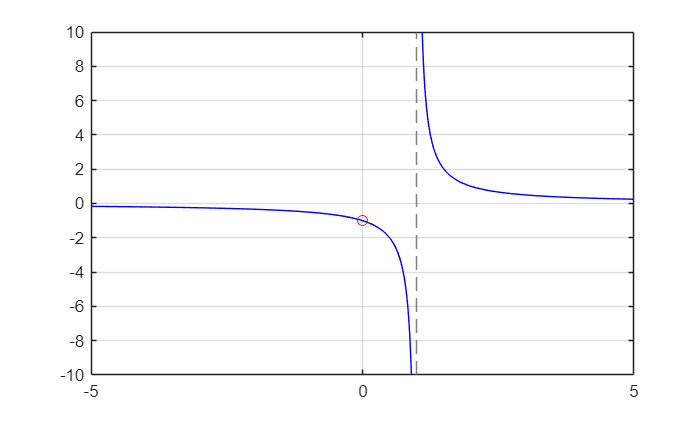

fplot(f,'b-')
grid on
hold on
plot(puntos_discontinuidad(1), L1,'ro')
hold off

En el punto de discontinuidad inevitable, la función presenta una asíntota vertical.

### Derivación

#### Definición

La derivada de una función $$f(x)$$ en punto $$a$ $viene dada por

			
$$	$$f'(a) = \lim\limits_{\Delta x \rightarrow 0} \frac{f(a+\Delta x)-f(a)}{\Delta x} $$$$


Así, podemos calcular la derivada por la definición:

#### Comando `diff`

Pero también podemos utilizar la función `diff`. Al igual que` limit, diff `acepta tanto funciones anónimas como simbólicas:

**Ejemplo**: Calculamos $ $f'(x)$ $siendo $$f(x) ={x^4 - x^3 + 5}$$ usando ambos comandos:

1. Definimos la función:

clearvars
syms x real
f(x) = (x^4 - x^3 + 5)   % funcion simbólica

$$f(x) = x^{4}-x^{3}+5$$

2. Calculamos la derivada por la definición:

syms dx
df1(x) = limit ( (f(x+dx) - f(x))/dx, dx, 0)

$$df1(x) = 4\,x^{3}-3\,x^{2}$$

3. Calculamos la derivada utilizando el comando `diff`: 

df2(x) = diff(f)

$$df2(x) = 4\,x^{3}-3\,x^{2}$$

Ambas opciones dan mismo resultado.

#### Derivadas de orden superior

Las **derivadas de orden superior** se refieren a la derivación repetida de una función. Para calcular la derivada de orden superior:

Por ejemplo, para la segunda derivada:

d2f(x) = diff(f, x, 2)

$$d2f(x) = 12\,x^{2}-6\,x$$

**Ejercicio**: Calcula las derivadas de la función  $f(x) = sen(x)$ hasta el cuarto orden. Comprueba que $f^{(4)}(x) = f(x)$.

% escribe aquí el código:




Solución:

clearvars
syms x real
f(x) = sin(x);
df(x) = diff(f)

$$df(x) = \cos\left(x\right)$$

d2f(x) = diff(f, x, 2) % que es equivalente a d2f(x) = diff(df)

$$d2f(x) = -\sin\left(x\right)$$

d3f(x) = diff(f,x,3)

$$d3f(x) = -\cos\left(x\right)$$

d4f(x) = diff(f,x,4)

$$d4f(x) = \sin\left(x\right)$$

**Ejemplo: **Siendo $$f(x) = \frac{sen(x)^4}{x^2 + e^x}$$, calcula $$f'(\pi)$$ y$ $f''(-4)$$:

clearvars
syms x real

f(x) =  sin(x)^4 / (x^2 + exp(x));  % funcion simbólica
f_prima(x) = diff(f, x, 1);  % derivada de orden 1
f_prima2(x) = diff(f, x, 2);  % derivada de orden 2

f_prima_pi = double(f_prima(pi))  % f'(x=pi)

f_prima_pi = 0

f_prima2_4 = double(f_prima2(-4))  % f''(x=-4)

f_prima2_4 = 0.0385

#### Recta tangente

Con lo que hemos visto ahora podríamos calcular (y dibujar) las rectas tangentes y normales a una curva dada.

- Recta tangente: $$$y-f(a) = f'(a)(x-a)$$$

- Recta normal (perpendicular a la recta tangente):$ $$y-f(a) =-\frac{1}{f'(a)}(x-a)$$$

**Ejemplo:** Calculamos las tangentes a $$f(x) = x^3 - 3x$$ que sean paralelas a la recta $ $y = 6x + 10$$. Representa en una misma figura$ $f(x)$$ (en rojo) y las tangentes halladas (con línea discontinua) en el dominio $$[-5, 5]$$. Pon un título y una leyenda adecuada. 

clearvars
syms x real
f(x) = x^3 - 3*x;

Calculamos la primera derivada:

df(x) = diff(f, x)  % derivada de orden 1

$$df(x) = 3\,x^{2}-3$$

Para encontrar una recta tangente a $f(x)$que sea paralela a la recta  $ $y = 6x + 10$$,  debemos hallar el punto en el cual la derivada  $f'(x)$  es igual a 6, ya que la pendiente de la tangente debe coincidir con la pendiente de la recta dada para que sean paralelas.

a = double(solve(df == 6))

a =     1.7321
   -1.7321


Son dos puntos. Hallamos las rectas tangentes en cada una:

rt1 = df(a(1))*(x-a(1)) + subs(f, a(1))  % eq. RT en x = a(1)

$$rt1(x) = 6\,x-6\,\sqrt{3}$$

rt2 = df(a(2))*(x-a(2)) + subs(f, a(2))  % eq. RT en x = a(1)

$$rt2(x) = 6\,x+6\,\sqrt{3}$$

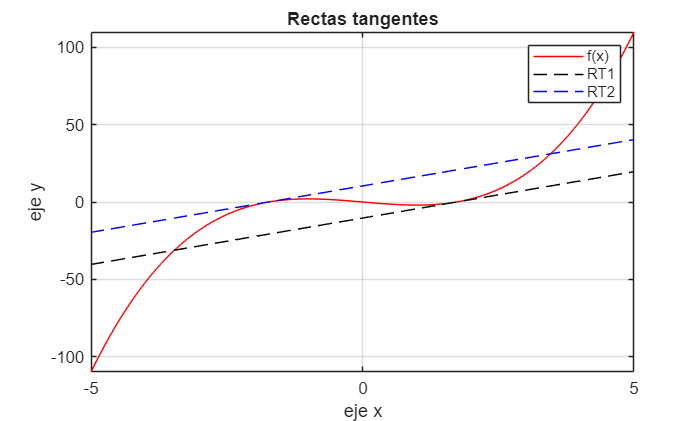

fplot(f,[-5,5],'r');  hold on % dibujo f
fplot(rt1,'k--');  % dibujo recta tangente en x = a(1)
fplot(rt2,'b--');  % dibujo recta tangente en x = a(2)
grid on
legend('f(x)', 'RT1', 'RT2')
xlabel('eje x'), ylabel('eje y')
title('Rectas tangentes')
hold off

### Polinomio de Taylor

Sea $$f(x)$$ una función derivable $$n$$ veces en el punto$ $x = a$$. Se define el **polinomio de Taylor** de grado $$n$$ correspondiente a la función $$f$$ en $$x = a$$ como:

		
$$$$
		P_n(f,a) = f(a)+f'(a)(x-a) + \frac{f''(a)}{2!}(x-a)^2
	+ \frac{f'''(a)}{3!}(x-a)^3 + \ldots +\frac{f^{(n)}(a)}{n!}(x-a)^n $$$$


Si $$a = 0$$, el polinomio se llama **polinomio de Maclaurin**.

En base a esta definición, y con lo que hemos visto hasta ahora, ya podríamos calcular polinomios de Taylor.

**Ejemplo:** Calculamos el polinomio de Taylor de grado 3 de la función $$f(x)=x \,sen(x+1)$$ en el punto $$a=0$$:

clearvars
syms x real
f(x) = x*sin(x+1);          % funcion simbolica
df1(x) = diff(f, x, 1);     % primera derivada de f
df2(x) = diff(f, x, 2);     % segunda derivada de f
df3(x) = diff(f, x, 3);     % tercera derivada de f

a = 0;  % punto de aplicacion del desarrollo
pt3(x) = f(a)+df1(a)*(x-a)+df2(a)/factorial(2)*(x-a)^2 + df3(a)/factorial(3)*(x-a)^3

$$pt3(x) = -\frac{\sin\left(1\right)\,x^{3}}{2}+\cos\left(1\right)\,x^{2}+\sin\left(1\right)\,x$$

Representamos la función y el polinomio de Taylor:

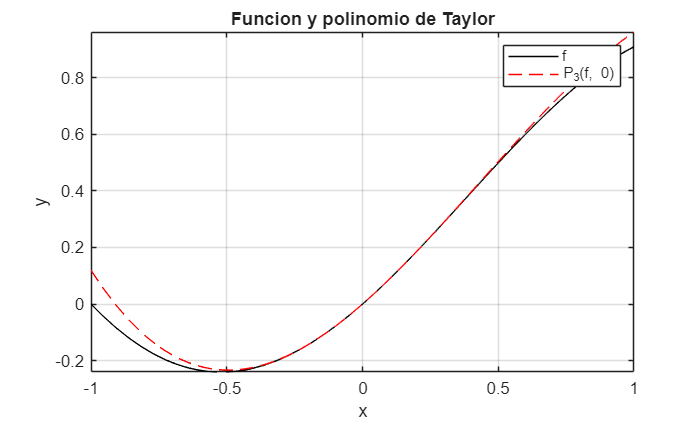

fplot(f, [-1 1],'k');
hold on
fplot(pt3, [-1 1],'r--');
grid on
xlabel('x'), ylabel('y')
legend('f', 'P_3(f, 0)')
title('Funcion y polinomio de Taylor')
hold off

#### Comando `taylor`

El comando `taylor` de MATLAB permite calcular directamente el polinomio de Tayor (de cualquier grado) para una cierta función (en cualquier punto). Dicha función puede estar definida como anónima o como simbólica. El resultado que devuelve `taylor `es siempre una expresión simbólica.

Fíjate en que los argumentos de entrada `ExpansionPoint` y` Order` son opcionales. Si estos argumentos no se especifican, `taylor` calcula por defecto el polinomio de Taylor de grado 5 centrado en el punto $$x=0$$. Consulta la [documentación](https://es.mathworks.com/help/symbolic/sym.taylor.html) si quieres obtener más información.

**Ejemplo: **Utilizamos el comando `taylor` para calcular el polinomio de Taylor de grado 3 de la función $$f(x)=xsen(x+1)$$ en el punto $$x=0$$. A continuación, utiliza dicho polinomio para obtener un valor aproximado de $$0.15 \cdot sen(1.15)$$. ¿Qúe error porcentual se comete en la aproximación?

1. Definimos la función (podría ser anónima o simbólica):

syms x real
f = @(x)  x*sin(x+1);  % funcion anonima
class(f)

ans = 'function_handle'

2. Calculamos el polinomio de Taylor:

pt3= taylor(f, x, 0, 'Order', 3+1)  % polinomio de Taylor de orden 3 de f en el punto 0

$$pt3 = -\frac{\sin\left(1\right)\,x^{3}}{2}+\cos\left(1\right)\,x^{2}+\sin\left(1\right)\,x$$

class(pt3)

ans = 'sym'

El resultado es una variable (expresión) simbólica. Sin embargo,  si añadimos el argumento  (`pt3(x) =` ...), el resultado será una función simbólica:

pt3(x) = taylor(f, x, 0, 'Order', 3+1)  % polinomio de Taylor de orden 3 de f en el punto 0

$$pt3(x) = -\frac{\sin\left(1\right)\,x^{3}}{2}+\cos\left(1\right)\,x^{2}+\sin\left(1\right)\,x$$

class(pt3)

ans = 'symfun'

3. Calculamos el valor exacto y valor aproximado:

ve = 0.15*sin(1.15)     % valor exacto

ve = 0.1369

va = double(pt3(0.15))  % valor aproximado (necesitaremos que x=0.15)

va = 0.1370

4. Calculamos el error:

err = 100*abs((va-ve)/ve)  % error: 0.03%

err = 0.0313

#### **Comando **`taylortool`

Además del comando `taylor`, MATLAB cuenta con una herramienta gráfica para el cálculo (y visualización) de polinomios de Taylor. Para activarla, bastará con teclear` taylortool` en la ventana de comandos. Esto abrirá una ventana gráfica en la que se puede introducir por pantalla la función a aproximar, el grado que se desee para el polinomio de Taylor y el intervalo en el que se quieren representar la función y el polinomio aproximador.

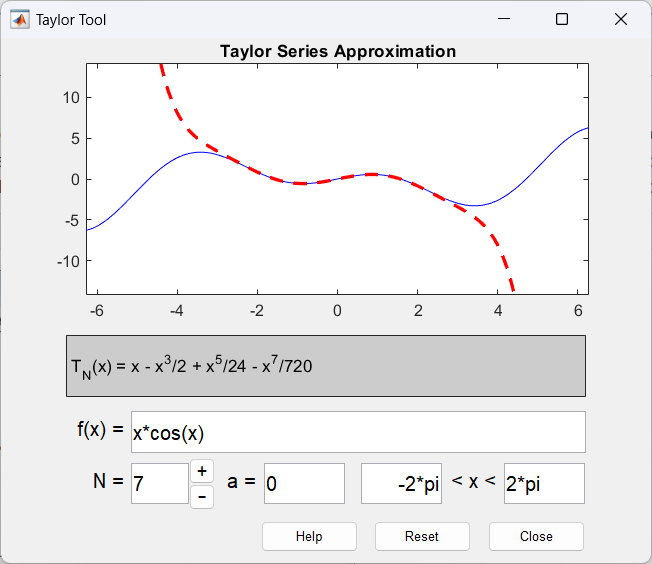

- **f(x) =**: Este campo muestra la función que se está aproximando, en este caso,$ f(x) = x \cdot \cos(x)$.

- **N**: Es el grado del polinomio de Taylor.

- **a =**: Es el punto alrededor del cual se está realizando la aproximación de Taylor. Por defecto, $a=0$, lo que significa que se está usando un polinomio de Maclaurin).

- **Rango de x**: Indica el intervalo de valores de $x$ para los que se realiza la aproximación.

**Ejercicio:** Comprueba, para la función $$f(x) = e^x \cos x$$, en un entorno del punto $$x=4$$, que a medida que el grado del polinomio de Taylor crece, éste aproxima mejor a $$f$$ y sobre un intervalo mayor. Utiliza para ello la herramienta `taylortool.`

### Ejercicios propuestos

1. Utiliza la expresión $ $\frac{f(x+\Delta x)-f(x)}{\Delta x}$$ para calcular un valor aproximado de $$\frac{d}{dx} \left( \frac{\ln(1 + x^2)}{sen^2x} \right)$$ en $$x_0 = 1$$ tomando $$\Delta x = \lbrace 0.1; 0.05; 0.0025 \rbrace$.$

 A continuación, calcula el valor exacto de la derivada usando los comandos `limit` y `diff`. Compara las aproximaciones obtenidas con el valor exacto en términos de error porcentual $$\left( \vert \frac{valor_{aprox} - valor_{exacto}}{valor_{exacto}} \vert \cdot 100 \% \right)$$.

% escribe aquí el código:




Solución:

soluciones(1)

Ejercicio 1:
dx = 0.1000: df_aprox(1) = 0.1950, error = 25.64 %
dx = 0.0500: df_aprox(1) = 0.1745, error = 12.46 %
dx = 0.0025: df_aprox(1) = 0.1561, error = 0.61 %


2. Halla el punto $$P$$ donde se cortan las funciones$ $f(x) = \frac{2}{x}$$ y $$g(x) = \sqrt{x^2 - 3}$$. Representa en una misma figura $$f$$ (en rojo) y $$g$ $(en azul) en $$[0,5] \times [0,3]$$. Pon una leyenda que identifique cada curva y un título. Halla la ecuación de la tangente a cada curva en $$P$$, dibuja ambas rectas (en el mismo color que la curva correspondiente pero en línea discontinua) y comprueba que son perpendiculares. 

% escribe aquí el código:





Solución:

Ejercicio 2:


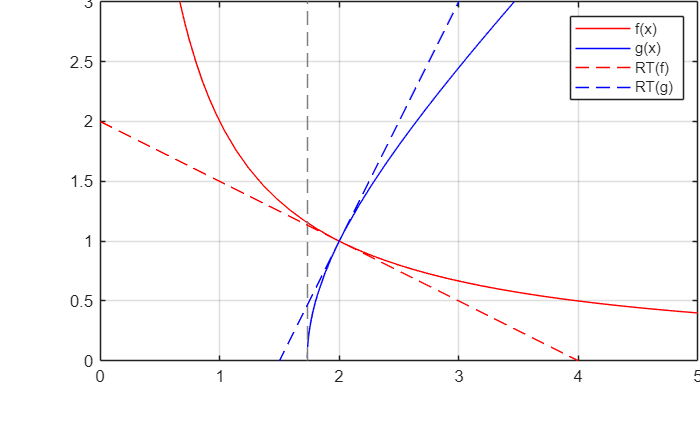

soluciones(2)

3. Representa la gráfica de la circunferencia$ $x^2 + y^2 + 2y = 9$$ en color negro y con una línea gruesa. Halla todas las rectas tangentes y normales a la circunferencia en el punto $$x_0 = 2$$ y represéntalas en línea discontinua en el dominio $$[-6,6] \times [-8,8]$$. Pon un título.

% escribe aquí el código:





Solución:

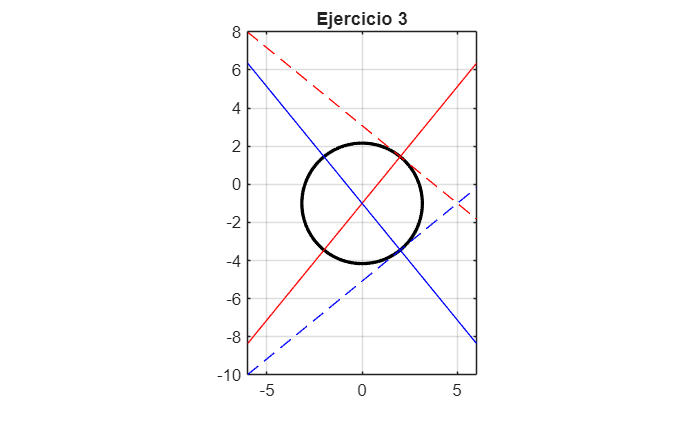

soluciones(3)

4. Considera la función $$f(x)=x^4-5x^3+5x^2+x+2$$

- Calcula el polinomio de Taylor de grado 1 de $$f$$ en $$x=2$$. Comprueba que se trata de la recta tangente a $$f$$ en dicho punto.

- Calcula los polinomios de Taylor de grado 2,3,4,5,10. ¿Qué ocurre a partir de grado 4?

% escribe aquí el código:




Solución:

soluciones(4)

Ejercicio 4:
Polinomio de Taylor: P1(x) = 14 - 7*x,
Recta Tangente:          y = 14 - 7*x
Orden 2: 

$$pt(x) = 14-{\left(x-2\right)}^{2}-7\,x$$

Orden 3: 

$$pt(x) = 3\,{\left(x-2\right)}^{3}-{\left(x-2\right)}^{2}-7\,x+14$$

Orden 4: 

$$pt(x) = 3\,{\left(x-2\right)}^{3}-{\left(x-2\right)}^{2}-7\,x+{\left(x-2\right)}^{4}+14$$

Orden 5: 

$$pt(x) = 3\,{\left(x-2\right)}^{3}-{\left(x-2\right)}^{2}-7\,x+{\left(x-2\right)}^{4}+14$$

Orden 10: 

$$pt(x) = 3\,{\left(x-2\right)}^{3}-{\left(x-2\right)}^{2}-7\,x+{\left(x-2\right)}^{4}+14$$

A partir de grado 4, todos los polinomios de Taylor son idénticos. 
Esto se debe a que la función original es un polinomio de grado 4, 
por lo que su polinomio de Taylor de grado 4 ya es la expresión exacta. 
Los términos adicionales en polinomios de mayor grado serán cero, 
ya que las derivadas de quinto orden en adelante son cero.


5. Considera la función $$f(x) =\ln\left(\frac{x+2}{2x-2}\right)$$

-  Dibuja en una misma gráfica $$f$ $y sus polinomios de Taylor de orden $$1$, $2$ y $3$$ en torno al punto$ $x=4$$.

- ¿Cuál es el grado del polinomio de Taylor en $$x=4$$ que habría que considerar para llegar a aproximar$ $\ln\left(\frac{6.1}{6.2}\right)$$ con un error porcentual inferior al $ $0.05\%$$?

% escribe aquí el código:






Solución:

Ejercicio 5:


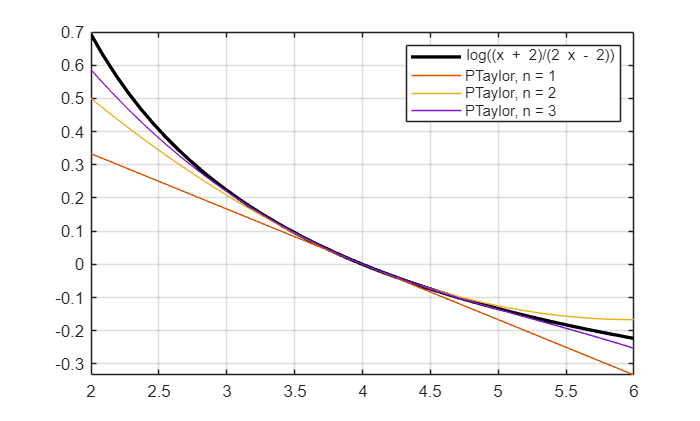

Grado 1: Error = 2.4977 %
Grado 2: Error = 0.0647 %
Grado 3: Error = 0.0017 %


soluciones(5)

6. Considera la función $$f(x)=\sqrt{1-\frac{x}{2}}$$

- Obtén el polinomio de Mclaurin de orden 3 para $$f(x)$$ y utilízalo para dar un valor aproximado de$ $\sqrt{0.5}$$. ¿Qué error porcentual se comete?

- Diseña un bucle que guarde en un vector el error porcentual cometido en la aproximación del apartado anterior para polinomios de Maclaurin de grado 3, 5, 8, 10, 12. Dibuja ese error en función del grado del polinomio aproximador (Utiliza el comando[ `semilogy`](https://es.mathworks.com/help/matlab/ref/semilogy.html) en lugar de `plot`). ¿Qué conclusión sacas?

- Repite el experimento propuesto en el apartado anterior pero con el objetivo de encontrar valores aproximados para $$\sqrt{0.75}$$. ¿Cómo influye el hecho de acercarse al punto en el que se hace el desarrollo ($$x=0$$ en este caso)?	

% escribe aquí el código:






Solución:

Ejercicio 6:


$$maclaurin3(x) = -\frac{x^{3}}{128}-\frac{x^{2}}{32}-\frac{x}{4}+1$$

Valor exacto: 0.707107, Valor aproximado: 0.710938, Error = 0.5417 %

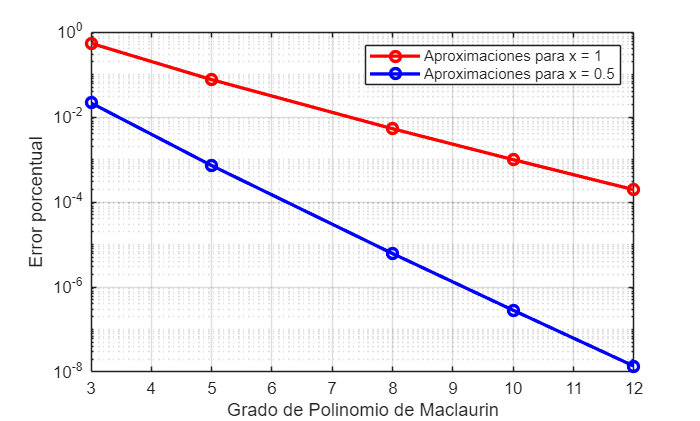

soluciones(6)

### Resumen

**Límite**

- [`limit`](https://es.mathworks.com/help/symbolic/sym.limit.html)**:** Se utiliza para calcular el límite (y los límites laterales) de una función, ya sea anónima o simbólica. 

- [`solve`](https://es.mathworks.com/help/symbolic/sym.solve.html)**:** Se emplea para resolver ecuaciones simbólicas (por ejemplo, para encontrar puntos de discontinuidad en la función).

**Derivación**

- [`diff`](https://es.mathworks.com/help/symbolic/diff.html)**:** Calcula la derivada de una función de manera simbólica. También permite calcular derivadas de orden superior.

**Polinomio de Taylor**

- [`taylor`](https://es.mathworks.com/help/symbolic/sym.taylor.html)**:** Calcula el polinomio de Taylor de una función, permitiendo especificar el punto de expansión y el grado del polinomio. Los argumentos adicionales como el punto de expansión y el grado son opcionales; si no se especifican, se calcula un polinomio de Taylor de grado 5 centrado en 0.

- [`taylortool`](https://es.mathworks.com/help/symbolic/taylortool.html)**:** Herramienta gráfica de MATLAB que facilita el cálculo y visualización de polinomios de Taylor. Permite interactuar con la función a aproximar, elegir el grado del polinomio, el punto de expansión y el rango de valores para la variable.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n");
        syms x real
        f(x) = log(1+x^2)/sin(x)^2;

        x0 = 1;
        df(x) = diff(f);
        df_exacto = double(df(x0));
        for dx = [0.1, 0.05, 0.0025]
            df_aprox = double(( f(x0+dx) - f(x0))/dx);

            error = abs( (df_aprox - df_exacto)/df_exacto)*100;
            fprintf("dx = %.4f: df_aprox(1) = %.4f, error = %.2f %%\n",dx,df_aprox,error)
        end

    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        syms x real
        f(x) = 2/x;
        g(x) = sqrt(x^2-3);
        fplot(f,[0 5],'r')
        hold on
        fplot(g,[0,5],'b')

        df(x) = diff(f);
        dg(x) = diff(g);
        P = solve(f-g);
        rt1(x) = df(P)*(x-P) + f(P);
        rt2(x) = dg(P)*(x-P) + g(P);

        fplot(rt1,[0 5],'r--')
        fplot(rt2,[0,5],'b--')

        axis equal
        ylim ([0 3])
        grid on
        legend('f(x)','g(x)','RT(f)','RT(g)')
        hold off
    case 3
        syms x y
        f(x,y) = x^2 + y^2 +2*y-9;
        fimplicit(f,[-6 6 -8 8],'k','LineWidth',2)
        axis equal
        grid on
        hold on
        y = solve(f,y); % despejamos y
        y1(x) = y(1);
        y2(x) = y(2);
        dy1 = diff(y1);
        dy2 = diff(y2);
        x0 = 2;
        rt1(x) = dy1(x0)*(x-x0) + y1(x0);
        rt2(x) = dy2(x0)*(x-x0) + y2(x0);
        rn1(x) = -1/dy1(x0)*(x-x0) + y1(x0);
        rn2(x) = -1/dy2(x0)*(x-x0) + y2(x0);
        fplot(rt1,'r--')
        fplot(rt2,'b--')
        fplot(rn1,'r-')
        fplot(rn2,'b-')
        title('Ejercicio 3')
        hold off
    case 4
        % Ejercicio 4:
        fprintf("Ejercicio 4:\n");
        syms x real
        f(x) = x^4 -5*x^3 + 5*x^2 + x + 2;
        a = 2;
        %Polinomio de Taylor:

        pt1(x) = taylor(f,x,a,'Order',2);
        % Recta tangente:
        df = diff(f);

        rt(x) = df(a)*(x-a) + f(a);
        fprintf("Polinomio de Taylor: P1(x) = %s,\nRecta Tangente:          y = %s\n",char(pt1),char(rt))
        for k = [2,3,4,5,10]
            fprintf("Orden %d: ",k)
            pt(x) = taylor(f,x,a,'Order',k+1)
        end
        fprintf("A partir de grado 4, todos los polinomios de Taylor son idénticos. \nEsto se debe a que la función original es un polinomio de grado 4, \npor lo que su polinomio de Taylor de grado 4 ya es la expresión exacta. \nLos términos adicionales en polinomios de mayor grado serán cero, \nya que las derivadas de quinto orden en adelante son cero.\n")

    case 5
        % Ejercicio 5:
        fprintf("Ejercicio 5:\n");
        syms x real
        f(x) = log((x+2)/(2*x-2));
        a = 4; da = 2;
        fplot(f,[a-da,a+da],'k-','LineWidth',2)
        grid on
        hold on
        for k = 1:3
            pt(x) = taylor(f,x,a,'Order',k+1);
            leg = ['PTaylor, n = ',num2str(k)];
            fplot(pt,[a-da,a+da],'DisplayName',leg);
        end
        hold off
        legend
        x1 = 4.1;
        ve = double(f(x1));  % valor exacto
        err = 1;
        tol = 0.05;
        k = 0;
        while err > tol
            k = k+1;
            pt(x) = taylor(f,x,a,'Order',k+1);
            va = double(pt(x1));
            err=abs( (va-ve)/ve)*100;
            fprintf("Grado %d: Error = %.4f %%\n",k,err)
        end
    case 6
        % Ejercicio 6:
        fprintf("Ejercicio 6:\n");
        syms x real
        f(x) = sqrt(1-x/2);
        %1.
        maclaurin3(x) = taylor(f,x,0,'Order',4)
        x1 = solve(f-sqrt(0.5));
        va = double(maclaurin3(x1));
        ve = f(x1);
        err = abs( (va-ve)/ve)*100;
        fprintf("Valor exacto: %f, Valor aproximado: %f, Error = %.4f %%",ve, va,err)
        grados = [3,5,8,10,12];
        errores = zeros(1,length(grados));
        for k = 1:length(grados)
            order = grados(k)+1;
            pt(x) = taylor(f,x,0,'Order',order);
            va = double(pt(x1));
            errores(k)=abs( (va-ve)/ve)*100;
        end
        semilogy(grados,errores,'r-o','LineWidth',2,'DisplayName','Aproximaciones para x = 1')
        grid on
        xlabel('Grado de Polinomio de Maclaurin')
        ylabel('Error porcentual')
        %----- repetimos todo para sqrt(0.75):
        x2 = solve(f-sqrt(0.75));
        ve = f(x2);
        errores2 = zeros(1,length(grados));
        for k = 1:length(grados)
            order = grados(k)+1;
            pt(x) = taylor(f,x,0,'Order',order);
            va = double(pt(x2));
            errores2(k)=abs( (va-ve)/ve)*100;
        end
        hold on
        semilogy(grados,errores2,'b-o','LineWidth',2,'DisplayName','Aproximaciones para x = 0.5')
        hold off
        legend
end
end